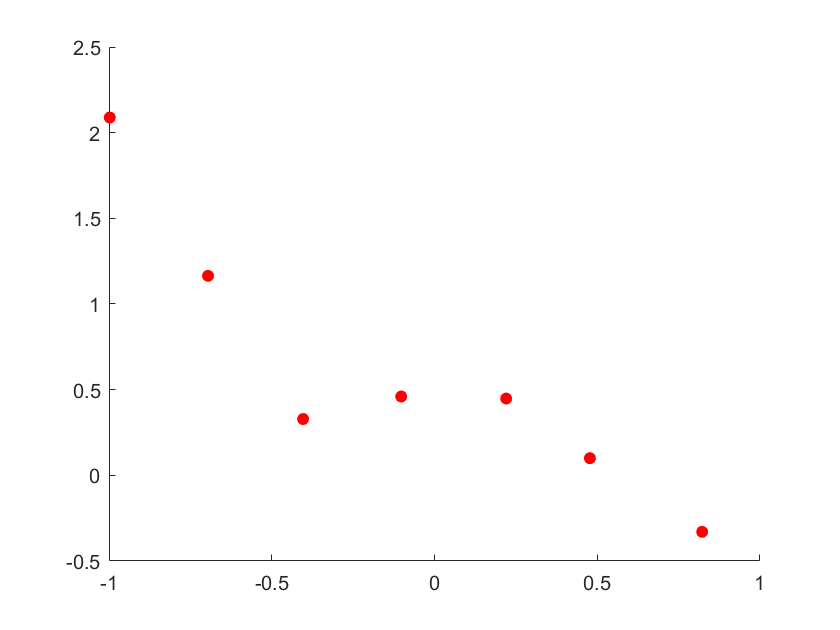

x = load("ex5Data\ex5Linx.dat");
y = load("ex5Data\ex5Liny.dat");
% 绘图
scatter(x, y,'filled','red')

x = [ones(m, 1), x, x.^2, x.^3 , x.^4, x.^5]

x =     1.0000   -0.9977    0.9954   -0.9931    0.9908   -0.9885
    1.0000   -0.6957    0.4841   -0.3368    0.2343   -0.1630
    1.0000   -0.4037    0.1630   -0.0658    0.0266   -0.0107
    1.0000   -0.1024    0.0105   -0.0011    0.0001   -0.0000
    1.0000    0.2202    0.0485    0.0107    0.0024    0.0005
    1.0000    0.4774    0.2279    0.1088    0.0520    0.0248
    1.0000    0.8223    0.6762    0.5560    0.4572    0.3759


% lambda
lambda1 = 0

lambda1 = 0

lambda2 = 1

lambda2 = 1

lambda3 = 10

lambda3 = 10

% 创建第一项为0的I
m = length(x); % 样本数
n = 5; % 特征数
I = eye(n + 1);
I(1, 1) = 0

I =      0     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


% 计算theta
theta1 = inv(x' * x + lambda1 * I) * x' * y

theta1 =     0.4725
    0.6814
   -1.3801
   -5.9777
    2.4417
    4.7371


theta2 = inv(x' * x + lambda2 * I) * x' * y

theta2 =     0.3976
   -0.4207
    0.1296
   -0.3975
    0.1753
   -0.3394


theta3 = inv(x' * x + lambda3 * I) * x' * y

theta3 =     0.5205
   -0.1825
    0.0606
   -0.1482
    0.0743
   -0.1280


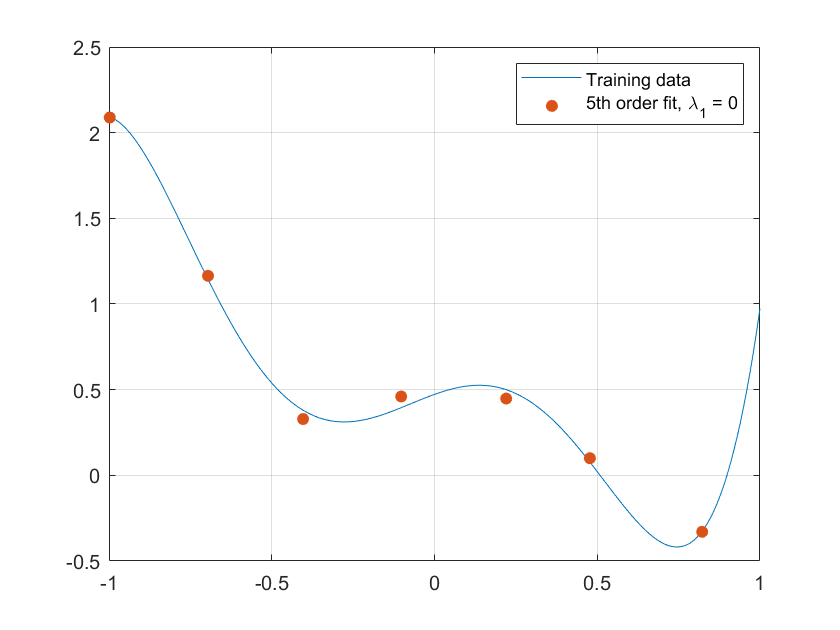

% 绘图
xx = -1.0:0.01:1.0;
yy1 = theta1(1,1) + theta1(2, 1)*xx + theta1(3, 1) * xx.^2 + theta1(4, 1) * xx.^3 + theta1(5, 1) * xx.^4 + theta1(6, 1) * xx.^ 5;
yy2 = theta2(1,1) + theta2(2, 1)*xx + theta2(3, 1) * xx.^2 + theta2(4, 1) * xx.^3 + theta2(5, 1) * xx.^4 + theta2(6, 1) * xx.^ 5;
yy3 = theta3(1,1) + theta3(2, 1)*xx + theta3(3, 1) * xx.^2 + theta3(4, 1) * xx.^3 + theta3(5, 1) * xx.^4 + theta3(6, 1) * xx.^ 5;
plot(xx, yy1);
hold on; % 保持图形
grid on;
xold = load('ex5Data\ex5Linx.dat');
scatter(xold, y,'filled');
hold off;legend('Training data', '5th order fit, \lambda_1 = 0'); 

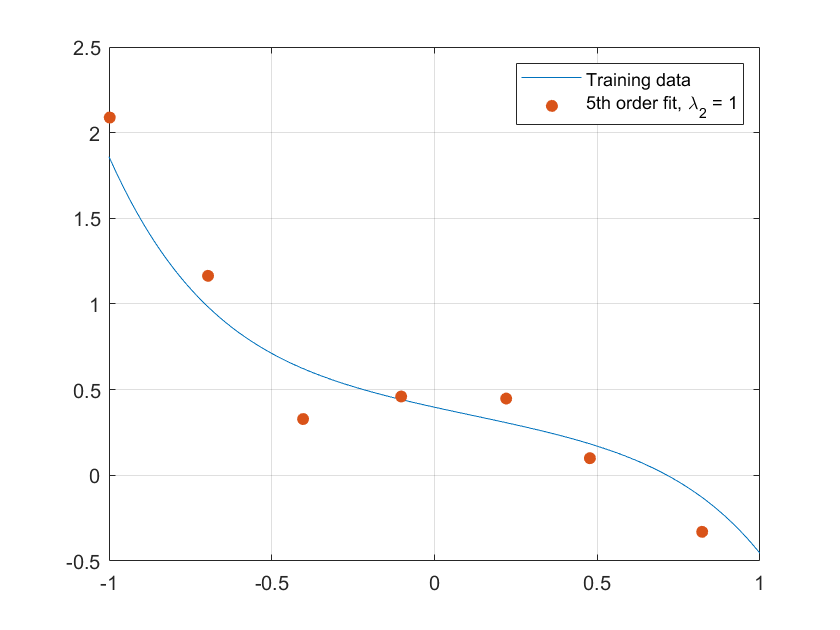

plot(xx, yy2);
hold on; % 保持图形
grid on;
scatter(xold, y,'filled');
hold off;legend('Training data', '5th order fit, \lambda_2 = 1');

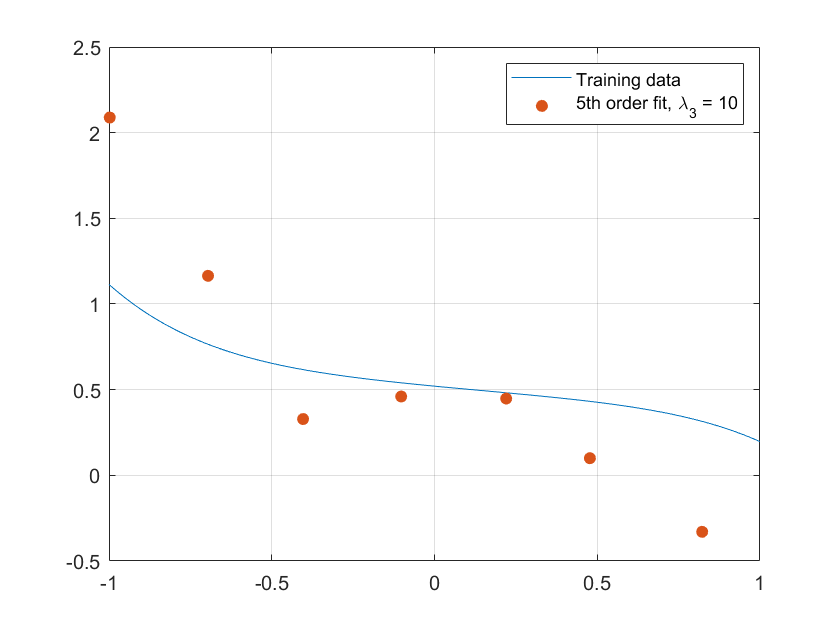

plot(xx, yy3);
hold on; % 保持图形
grid on;
scatter(xold, y,'filled');
hold off;legend('Training data', '5th order fit, \lambda_3 = 10');